# Metoda celor mai mici patrate

## Aproximare discreta

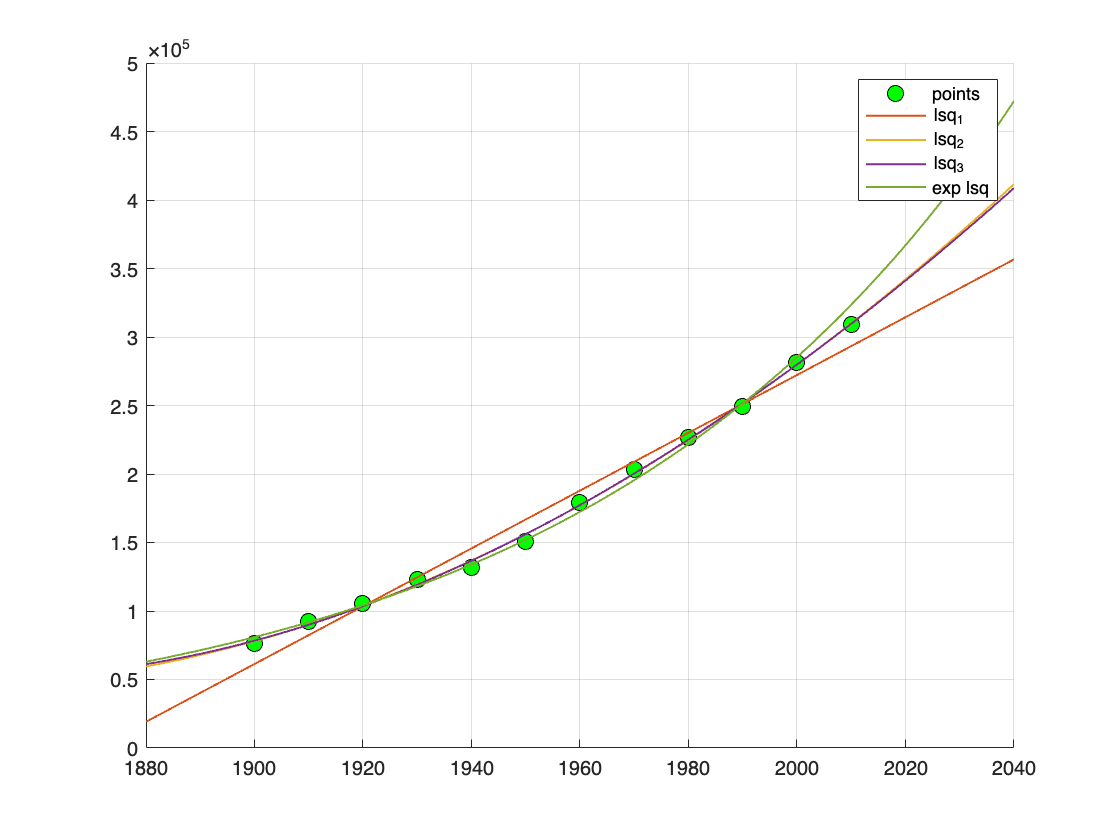

x=1900:10:2010;
f=[75995 91972 105710 123200 131670 150700 ...
179320 203210 226510 249630 281420 308790];
X=linspace(1880, 2040, 1000);

clf; hold on; grid on;

plot(x, f, 'ok', 'markerfacecolor', 'g', 'markersize', 8);
for k=1:3
    coefs=least_sq(x,f,k);
    vals=coefs(k+1);
    for i=k:-1:1
        vals=vals.*X + coefs(i);
    end
    plot(X, vals, 'linewidth', 1)
end

coefs=least_sq(x,log(f),1);
vals=exp(coefs(2) * X + coefs(1));
plot(X, vals, 'LineWidth', 1);
legend("points", "lsq_1", "lsq_2", "lsq_3", "exp lsq");

## Aproximare continua

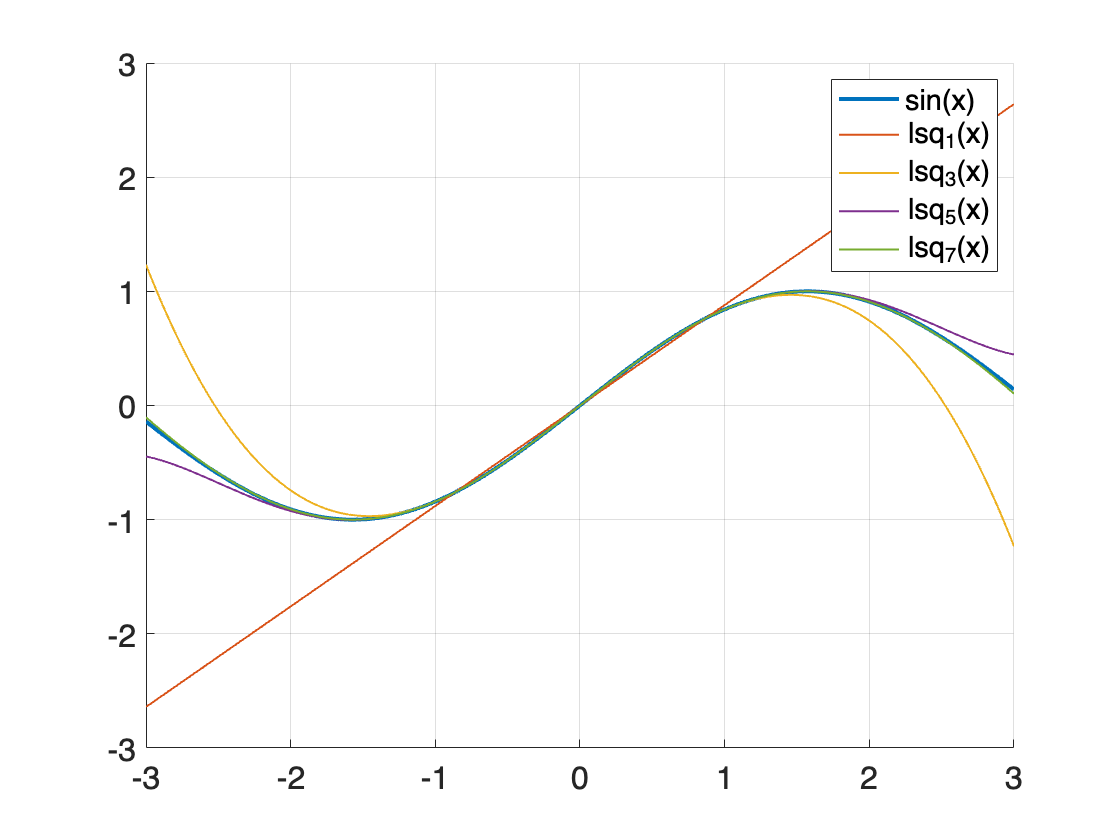

function plotContinousLsq(f, X, name)
    clf; hold on; grid on;
    plot(X, f(X), 'LineWidth', 2);
    for n=1:2:7
        y=least_sq_cont_Ceb1(f,n);
        plot(X, y(X), 'LineWidth', 1);
    end
    legend(name, "lsq_1(x)", "lsq_3(x)", "lsq_5(x)", "lsq_7(x)");
    set(gca,'fontsize',16);
end

f=@(x) sin(x);
X=linspace(-3, 3, 1000);
plotContinousLsq(f, X, "sin(x)")